ParentDir = "F:\YuLab\Work\GPS\Video";
TaskDir = uigetdir(ParentDir, "Choose animal directionory");

TrajGroupClassFile = dir(TaskDir+"\*TrajGroupClass*.mat");
if length(TrajGroupClassFile)>1
    fprintf("More than one TrajGroupClass found");
    return;
end

load(fullfile(TaskDir, TrajGroupClassFile.name));


D_dtw = cell(1, length(obj.Ports));

for j = 1:2

    disp(j)

    these_trials = find(obj.TrialInfo.PortCorrect==obj.Ports(j) & obj.TrialInfo.Cued==0 & obj.TrialInfo.Stage==1 & obj.TrialInfo.zi>0.5);
    these_trials_control = these_trials(obj.TrialInfo.Label(these_trials)=="Control");
    these_trials_chemo = these_trials(obj.TrialInfo.Label(these_trials)=="Chemo");

    M = cell(length([these_trials_control; these_trials_chemo]), 1);
    for t = 1:length(these_trials_control)
        M{t} = obj.AngleHeadMatIn(these_trials_control(t), 100:100+floor(1000*obj.HD(these_trials_control(t))));
    end
    for t = 1:length(these_trials_chemo)
        M{t+length(these_trials_control)} = obj.AngleHeadMatIn(these_trials_chemo(t), 100:100+floor(1000*obj.HD(these_trials_chemo(t))));
    end

    D_dtw{j} = zeros(length(M), length(M));
    for m = 1:length(M)
        for n = m+1:length(M)
            D_dtw{j}(m, n) = dtw(M{m}, M{n});
        end
    end
    % 填充对称位置
    D_dtw{j} = D_dtw{j} + D_dtw{j}';
    D_dtw{j} = normalize(D_dtw{j}(:), 'range');
    D_dtw{j} = reshape(D_dtw{j}, length(M), length(M));
end

     1

     2



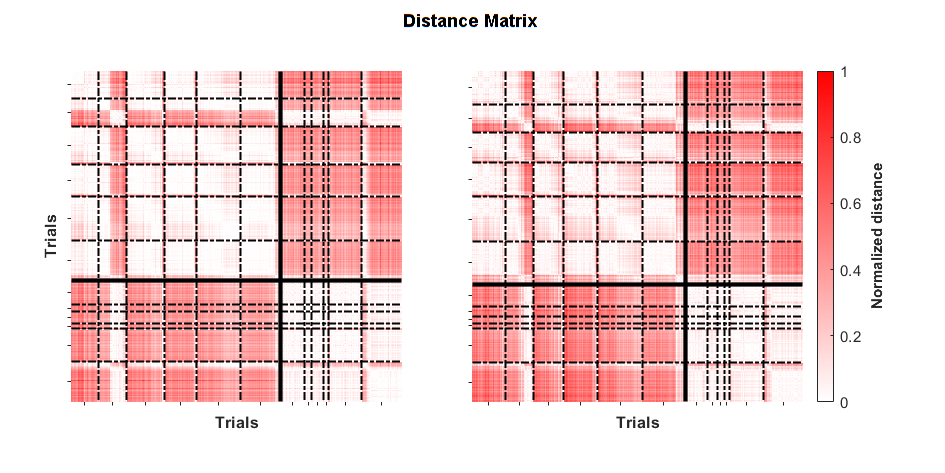

mycolormap = customcolormap([0 1], [1 0 0; 1 1 1]);

fig_rsm = figure(51); clf(51);
set(fig_rsm, 'Units', 'Centimeters', 'Position', [1 1 20 10], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig_rsm, 'units', 'normalized', 'position', [0.2 0.9 0.6 0.08],...
    'string', "Distance Matrix", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

for j = 1:2

    ax_rsm = axes;
    set(ax_rsm, 'Units', 'Centimeters', 'Position', [1.5+8.5*(j-1) 1.5 7 7], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'YDir', 'reverse');

    these_trials = find(obj.TrialInfo.PortCorrect==obj.Ports(j) & obj.TrialInfo.Cued==0 & obj.TrialInfo.Stage==1 & obj.TrialInfo.zi>0.5);

    these_trials_control = these_trials(obj.TrialInfo.Label(these_trials)=="Control");
    sessions_control = obj.TrialInfo.Session(these_trials_control);
    sessions_control_id = unique(sessions_control);
    num_trials_control = zeros(length(sessions_control_id), 1);
    for k = 1:length(sessions_control_id)
        num_trials_control(k) = sum(sessions_control==sessions_control_id(k));
    end

    these_trials_chemo = these_trials(obj.TrialInfo.Label(these_trials)=="Chemo");
    sessions_chemo = obj.TrialInfo.Session(these_trials_chemo);
    sessions_chemo_id = unique(sessions_chemo);
    num_trials_chemo = zeros(length(sessions_chemo_id), 1);
    for k = 1:length(sessions_chemo_id)
        num_trials_chemo(k) = sum(sessions_chemo==sessions_chemo_id(k));
    end

    session_seps = cumsum([num_trials_control; num_trials_chemo]) + 0.5;

    colormap(mycolormap);
    imagesc(D_dtw{j}); clim([0 1]);

    xline(session_seps(1:end-1), 'LineStyle', '-.', 'LineWidth', 1.2, 'Color', 'k', 'Alpha', 1);
    yline(session_seps(1:end-1), 'LineStyle', '-.', 'LineWidth', 1.2, 'Color', 'k', 'Alpha', 1);

    xline(length(these_trials_control)+0.5, 'LineStyle', '-', 'LineWidth', 2.5, 'Color', 'k', 'Alpha', 1);
    yline(length(these_trials_control)+0.5, 'LineStyle', '-', 'LineWidth', 2.5, 'Color', 'k', 'Alpha', 1);

    xlim([.5 length(these_trials)+.5]);
    ylim([.5 length(these_trials)+.5]);

    xticks(session_seps - [num_trials_control; num_trials_chemo] / 2); xticklabels([]);
    yticks(session_seps - [num_trials_control; num_trials_chemo] / 2); yticklabels([]);

    if j == 1
        ax_rsm.YLabel.String = "Trials";
        ax_rsm.YLabel.FontWeight = "Bold";
    end
    ax_rsm.XLabel.String = "Trials";
    ax_rsm.XLabel.FontWeight = "Bold";
end

ax_cb = axes;
set(ax_cb, 'Units', 'Centimeters', 'Position', [13.5 1.5 5 7], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', ...
    'Color', 'none', 'XColor', 'none', 'YColor', 'none');
cb = colorbar;
clim(ax_cb, [0 1]);
cb.FontSize = 9;
cb.Label.String = "Normalized distance";
cb.Label.FontSize = 9;
cb.Label.FontWeight = 'bold';

save_name = "DistDTWMatrix_" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_rsm, save_path);

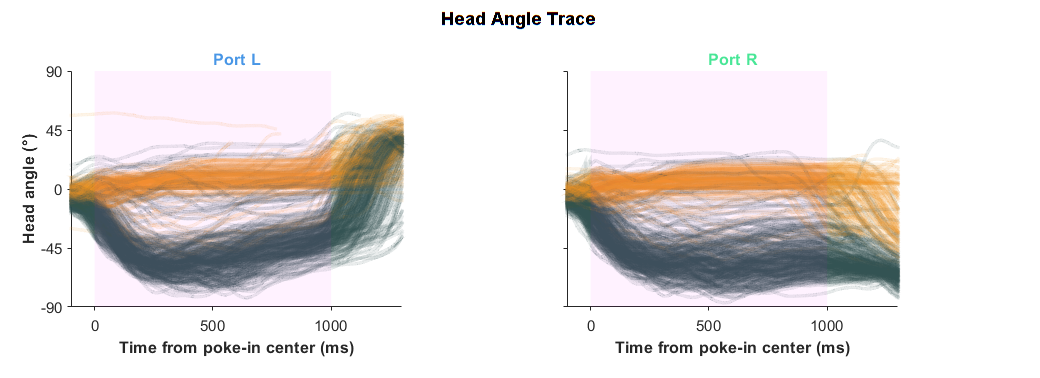

fig_trace = figure(52); clf(52);
set(fig_trace, 'Units', 'Centimeters', 'Position', [1 1 22 8], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig_trace, 'units', 'normalized', 'position', [0.2 0.9 0.6 0.08],...
    'string', "Head Angle Trace", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

plot_height = 5;
plot_width  = [9 14 19] / 2;

for j = 1:2

    ax_trace = axes;
    set(ax_trace, 'Units', 'Centimeters', 'Position', [1.5+10.5*(j-1) 1.5 2+5*obj.TaskFP plot_height], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

    fp_begin = 0;
    fp_end   = 1000*obj.TaskFP;

    these_trials = find(obj.TrialInfo.PortCorrect==obj.Ports(j) & obj.TrialInfo.Cued==0 & obj.TrialInfo.Stage==1 & obj.TrialInfo.zi>0.5);
    these_trials = these_trials(randperm(length(these_trials)));
    these_trials_control = these_trials(obj.TrialInfo.Label(these_trials)=="Control");
    these_trials_chemo = these_trials(obj.TrialInfo.Label(these_trials)=="Chemo");

    for k = 1:length(these_trials)
        switch obj.TrialInfo.Label(these_trials(k))
            case "Chemo"
                color_this = GPSColor.Treat;
            case "Control"
                color_this = GPSColor.Control;
        end
        patch(ax_trace, 'XData', [obj.TimePointsIn(1:100+1000*obj.TaskFP+300) nan], 'YData', [obj.AngleHeadMatIn(these_trials(k), (1:100+1000*obj.TaskFP+300)) nan], 'EdgeColor', color_this, 'EdgeAlpha', 0.1, 'LineWidth', 2)
    end

%     plot(ax_trace, obj.TimePointsIn(1:100+1000*obj.TaskFP+300), mean(obj.AngleHeadMatIn(these_trials_control, 1:100+1000*obj.TaskFP+300)), ...
%         'Color', GPSColor.Control, 'LineWidth', 4)
% 
%     plot(ax_trace, obj.TimePointsIn(1:100+1000*obj.TaskFP+300), mean(obj.AngleHeadMatIn(these_trials_chemo, 1:100+1000*obj.TaskFP+300)), ...
%         'Color', GPSColor.Treat, 'LineWidth', 4)

    patch(ax_trace, 'XData', [fp_begin fp_end fp_end fp_begin], 'YData', [-90 -90 90 90], 'FaceColor', 'm', 'FaceAlpha', 0.05, 'EdgeColor', 'none')

    set(ax_trace, 'XLim', [-100 1000*obj.TaskFP+300], 'YLim', [-90 90], 'XTick', 0:500:1500, 'YTick', -90:45:90);

    ax_trace.XLabel.String = "Time from poke-in center (ms)";
    ax_trace.XLabel.FontWeight = "bold";

    ax_trace.Title.String = "Port "+obj.Ports(j);
    ax_trace.Title.Color  = GPSColor.("Port"+obj.Ports(j));
    ax_trace.Title.FontWeight = "bold";

    if j == 1
        ax_trace.YLabel.String = "Head angle (°)";
        ax_trace.YLabel.FontWeight = "bold";
    end
    if j == 2
        ax_trace.YTickLabel = [];
    end

end

save_name = "HeadAngleTrace_" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_trace, save_path);

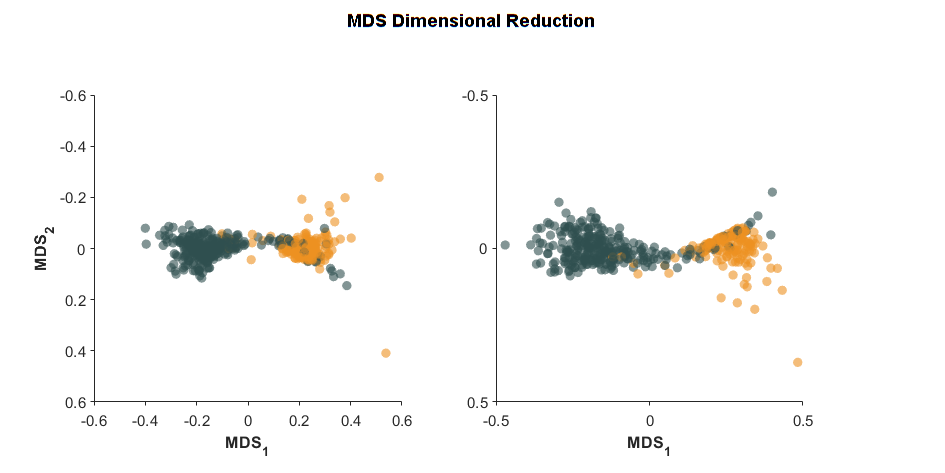

fig_mds = figure(54); clf(54);
set(fig_mds, 'Units', 'Centimeters', 'Position', [1 1 20 10], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig_mds, 'units', 'normalized', 'position', [0.2 0.9 0.6 0.08],...
    'string', "MDS Dimensional Reduction", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

MDS_score = cell(1, length(obj.Ports));
MDS_cost  = cell(1, length(obj.Ports));

for j = 1:2

    [MDS_score{j}, MDS_cost{j}] = cmdscale(D_dtw{j});

    these_trials = find(obj.TrialInfo.PortCorrect==obj.Ports(j) & obj.TrialInfo.Cued==0 & obj.TrialInfo.Stage==1 & obj.TrialInfo.zi>0.5);
    these_trials_control = these_trials(obj.TrialInfo.Label(these_trials)=="Control");
    these_trials_chemo = these_trials(obj.TrialInfo.Label(these_trials)=="Chemo");
    id_control = 1:length(these_trials_control);
    id_chemo = length(these_trials_control) + (1:length(these_trials_chemo));
    this_color = [repmat(GPSColor.Control, length(these_trials_control), 1); repmat(GPSColor.Treat, length(these_trials_chemo), 1)];
    id_shuffle = randperm(length(these_trials));

    ax_mds = axes;
    set(ax_mds, 'Units', 'Centimeters', 'Position', [2+8.5*(j-1) 1.5 6.5 6.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'YDir', 'reverse');

    scatter(ax_mds, MDS_score{j}(id_shuffle,1), MDS_score{j}(id_shuffle,2), 32, this_color(id_shuffle, :), 'filled', 'MarkerFaceAlpha', 0.6, 'MarkerEdgeColor', 'none');

    if j == 1
        ax_mds.YLabel.String = "MDS_2";
        ax_mds.YLabel.FontWeight = "Bold";
    end
    ax_mds.XLabel.String = "MDS_1";
    ax_mds.XLabel.FontWeight = "Bold";

    ax_mds.YLim = ax_mds.XLim;
end

save_name = "MDS_" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_mds, save_path);

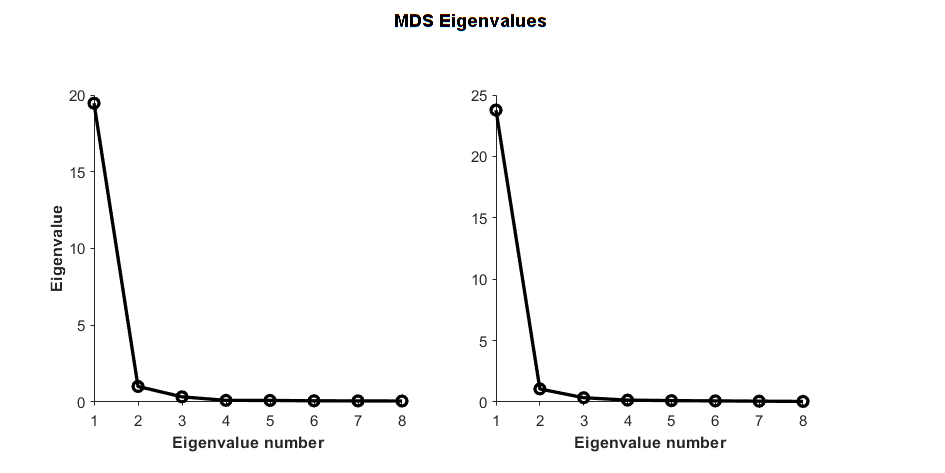

fig_mds_cost = figure(55); clf(55);
set(fig_mds_cost, 'Units', 'Centimeters', 'Position', [1 1 20 10], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig_mds_cost, 'units', 'normalized', 'position', [0.2 0.9 0.6 0.08],...
    'string', "MDS Eigenvalues", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

for j = 1:2

    ax_mds_cost = axes;
    set(ax_mds_cost, 'Units', 'Centimeters', 'Position', [2+8.5*(j-1) 1.5 6.5 6.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

    plot(ax_mds_cost, 1:8, MDS_cost{j}(1:8), '-ok', 'LineWidth', 2);

    if j == 1
        ax_mds_cost.YLabel.String = "Eigenvalue";
        ax_mds_cost.YLabel.FontWeight = "Bold";
    end

    ax_mds_cost.XLabel.String = "Eigenvalue number";
    ax_mds_cost.XLabel.FontWeight = "Bold";
    
    ax_mds_cost.XLim = [1 8];

end

save_name = "MDS_Eigenvalue_" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_mds_cost, save_path);

Mdl_cv = cell(1, length(obj.Ports));
Acc_cv = cell(1, length(obj.Ports));

MotorType = nan(length(obj.HD), 1);
for j = 1:2

    these_trials = find(obj.TrialInfo.PortCorrect==obj.Ports(j) & obj.TrialInfo.Cued==0 & obj.TrialInfo.Stage==1 & obj.TrialInfo.zi>0.5);
    these_trials_control = these_trials(obj.TrialInfo.Label(these_trials)=="Control");
    these_trials_chemo = these_trials(obj.TrialInfo.Label(these_trials)=="Chemo");

    id_control = 1:length(these_trials_control);
    id_chemo = length(these_trials_control) + (1:length(these_trials_chemo));

    y = [zeros(length(id_control), 1); ones(length(id_chemo), 1)];
    x = MDS_score{j}(:,1:2);

    Mdl = fitcdiscr(x, y);
    y_fit = predict(Mdl, x);
    MotorType([these_trials_control; these_trials_chemo]) = y_fit;

    cvp = cvpartition(y,'KFold',10);

    Mdl_cv{j} = fitcdiscr(x, y, "CrossVal", "on", "CVPartition", cvp);

    Acc_cv{j} = 1-kfoldLoss(Mdl_cv{j}, "Mode", "individual");

end

Acc_mean = cellfun(@(x) mean(x), Acc_cv);
Acc_std = cellfun(@(x) std(x), Acc_cv);
Acc_sem = Acc_std ./ sqrt(10);


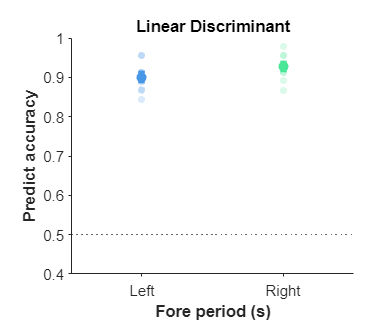


fig_mdl = figure(56); clf(56);
set(fig_mdl, 'Units', 'Centimeters', 'Position', [1 1 8 7], 'PaperPositionMode', 'Auto', 'Color', 'w');

ax_mdl = axes;
set(ax_mdl, 'Units', 'Centimeters', 'Position', [1.5 1.2 6 5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

yline(ax_mdl, .5, 'LineStyle', ':');

scatter(ax_mdl, 1, Acc_cv{1}, 18, 'Marker', 'o', 'MarkerEdgeColor', 'none', 'MarkerFaceColor', GPSColor.PortL, 'MarkerFaceAlpha', 0.2);
scatter(ax_mdl, 2, Acc_cv{2}, 18, 'Marker', 'o', 'MarkerEdgeColor', 'none', 'MarkerFaceColor', GPSColor.PortR, 'MarkerFaceAlpha', 0.2);

errorbar(ax_mdl, 1, Acc_mean(1), Acc_sem(1), 'Color', GPSColor.PortL, 'LineWidth', 2, 'LineStyle', 'none', 'Marker', 'o', 'MarkerFaceColor', GPSColor.PortL, 'MarkerEdgeColor', 'none', 'MarkerSize', 6, 'CapSize', 4)
errorbar(ax_mdl, 2, Acc_mean(2), Acc_sem(2), 'Color', GPSColor.PortR, 'LineWidth', 2, 'LineStyle', 'none', 'Marker', 'o', 'MarkerFaceColor', GPSColor.PortR, 'MarkerEdgeColor', 'none', 'MarkerSize', 6, 'CapSize', 4)

xlim(ax_mdl, [.5 2.5]); ylim([0.4 1]);
xticks(ax_mdl, [1 2]);
xticklabels(ax_mdl, {'Left', 'Right'});

xlabel(ax_mdl, 'Fore period (s)', 'FontWeight', 'bold');
ylabel(ax_mdl, 'Predict accuracy', 'FontWeight', 'bold');

title(ax_mdl, 'Linear Discriminant', 'FontWeight', 'bold');
save_name = "Classifier_" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_mdl, save_path);

Mdl = fitcdiscr(x, y);
y_fit = predict(Mdl, x);

correct_reject = sum(y==0 & y_fit==0) / sum(y==0)

correct_reject = 0.9078

hit = sum(y==1 & y_fit==1) / sum(y==1)

hit = 0.9630

false_alarm = sum(y==0 & y_fit==1) / sum(y==0)

false_alarm = 0.0922

miss = sum(y==1 & y_fit==0) / sum(y==1)

miss = 0.0370

% obj.TrialInfo = addvars(obj.TrialInfo, MotorType, 'NewVariableNames', "MotorType");
obj.TrialInfo.MotorType = MotorType;
obj.save(TaskDir);



table_name = "TrialInfo_" + obj.ANM + "_" + obj.Task + "_z.csv";
save_path = fullfile(TaskDir, table_name);
writetable(obj.TrialInfo, save_path)